## A MATLAB Live Script  for 2223-MA378: Runge's Example

This is an example of trying to apply Lagrange polynomial interpolation at equidistant points. See also Section 1-5 of the lecture notes.

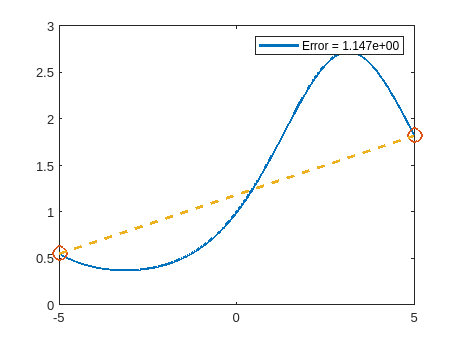

a=-5; b=5;
X = linspace(a,b,1001); 

f = @(x)exp(sin(x/2));
n=1;
xp = linspace(a,b,n+1);
C1 = polyfit(xp,f(xp),n);
p = @(x)polyval(C1,X);
Error = max(f(X)-p(X));
plot(X, f(X), xp, f(xp), 'o', X, p(X), '--', 'LineWidth', 2, 'MarkerSize',10);
legend(sprintf("Error = %8.3e", Error));